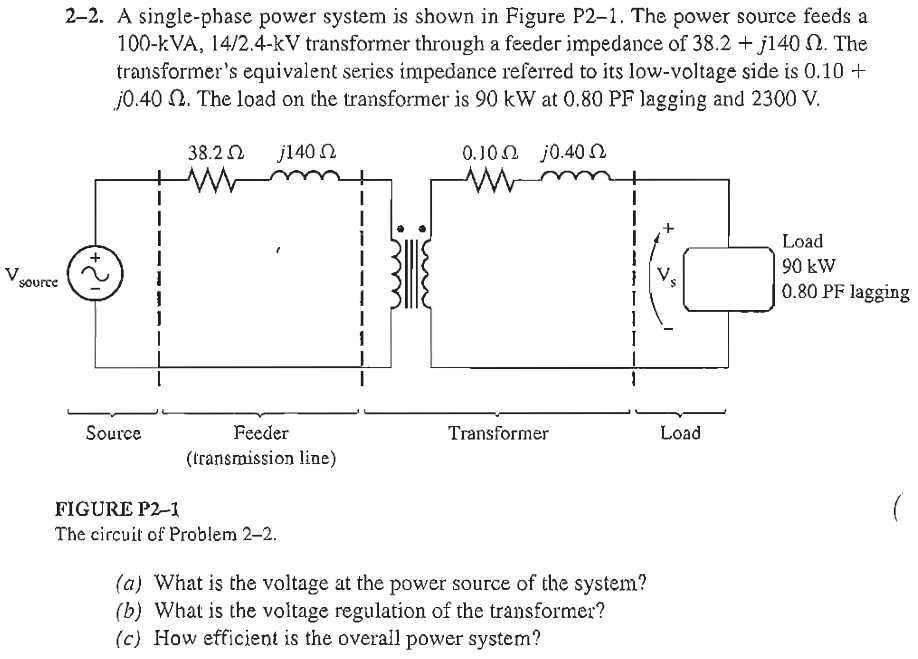

**2-2. 如圖 P2-1 所示，是一個單相電力系統。電力源透過具有阻抗 38.2 + j****140** **Ω**** 的饋電線，供電給額定容量為 100-kVA、14/2.4-kV 的變壓器。變壓器的等效串聯阻抗（參考至低壓側）為 0.10 + j****0.40** **Ω****。變壓器上的負載為 90 kW，功率因數為 0.80 滯後，負載電壓為 2300 V。**

**(a) 系統的電源端電壓是多少？**

**(b) 變壓器的電壓調整率是多少？**

**(c) 整個電力系統的效率是多少？**

負載功率 Sload� 代表的是「視在功率」（以伏安 VA 為單位），而 Pload� 則代表「有功功率」（以瓦特 W 為單位）。視在功率 S 是包含了有功功率 P 和無功功率 Q 的總合，並且與功率因數有關。

負載視在功率 Sload� 與有功功率 Pload� 和功率因數 PF 之間的關係如下：Sload = Pload / PF

**複功率 視在功率(apparent power) Sload�**：電路中電能的總流量，視在功率是電壓和電流的乘積，反映總功率需求，以伏安 (VA) 為單位 

視在功率 (VA) = 電壓 (V)×電流 (A)

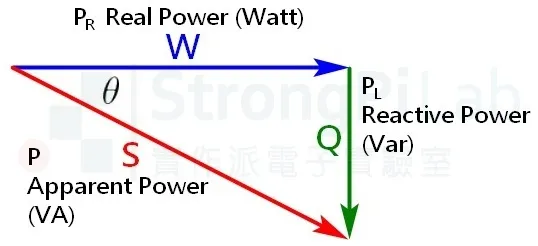

=> Sload = Vload * I*load� (I*load電流的複數共軛)

S = VΙ* = P + jQ

**功率因數(power factor) PF**：功率因數是有功功率與視在功率之比� 

=> PF = Pload / Sload =cos(θ) = Psc / (Vsc * Isc)

串聯電路 cos(θ) = R / Z 並聯電路 cos(θ) = Z / R

領前：表示電容性阻抗 // 電流領前電壓，功因角為負

滯後：表示電感性阻抗 // 電流滯後電壓，功因角為正

ex:theta = - 60 電流領前電壓，theta = 60 電流滯後電壓

提高PF供應較小電流

功率因數的值介於 0 到 1 之間，且功率因數「滯後」或「超前」會影響電流的相位角，數值越接近1，表示電路的功率因數越高，電路的效率越好；越接近 0 這樣電壓會偏低，電力系統運轉困難。

**實功率 有功功率 平均功率(average power) Pload�**： 實際消耗的有功功率，以瓦特 (W) 為單位 => Pload = Sload * PF

**虛功率 無功功率(reactive power) Qload：**� 是與相位角相關的無功成分，以乏 (VAR) 為單位

=> Qload = Sload * sin(θ) = Sload * sqrt(1-PF^2)

**負載電流 Iload�：**代表流過負載的電流 => Iload = Sload / Vload = Pload / (Vload * PF)

**變壓器等效阻抗（refer to low-voltage side)**：將變壓器的阻抗值轉換到其中一側（通常是低壓側）進行分析和計算，這樣可以使變壓器兩側的電流和電壓在同一側的阻抗參數下進行統一計算。

給定的**變壓器等效阻抗**為 Ztr �= 0.10 + j0.40 Ω，這表示該阻抗已經轉換到低壓側。因此，我們可以直接使用這個阻抗值進行低壓側的計算，而不必再進行額外的轉換。

如果變壓器的阻抗最初是在高壓側測量的，我們可以將其轉換到低壓側

Ztr_LV = Ztr_HV * (V_LV / V_HV) ^ 2

變壓器的等效阻抗會影響系統的電壓降、電壓調整率和損耗

- **電壓降**：當負載電流流過等效阻抗時會產生電壓降，影響低壓側的電壓水平。

- **電壓調整率**：等效阻抗越大，負載變動時的電壓變動也會越大。

- **損耗計算**：等效阻抗中的電阻部分（即 0.10 Ω）會導致功率損耗（I²R 損耗）

一次側電壓就是輸入端電壓(V_p)，二次側電壓就是輸出端電壓(V_s)

`變壓器能改變電壓和電流的準位，所以也改變了電壓對電流的比值及元件的視在阻抗（`apparent impedance`），如果二次側電流為 `I*S*`，二次側電壓為 `V*S*

% 系統參數
P_load = 90e3; % 負載功率，W (90kW)
PF = 0.80; % 功率因數 (滯後)
V_load = 2300; % 負載電壓，V

% 變壓器的電壓轉換比為 14 kV / 2.4 kV
V_LV = 2.4e3; % 低壓側電壓，V (2.4kV)
V_HV = 14e3; % 高壓測電壓，V (14kV)

% 計算負載電流
I_load = P_load / (V_load * PF); % 負載電流 (複數)
theta = acos(PF); % PF = cos(theta)
I_load = I_load * (cos(theta) - 1j * sin(theta)); % 複數形式
disp(['I_load = ', num2str(real(I_load)), ' + j', num2str(imag(I_load))]);

I_load = 39.1304 + j-29.3478


[theta, I_load_deg] = cart2pol(real(I_load), imag(I_load));
disp(['I_load = ', num2str(I_load_deg), ' /_', num2str(theta * 180/pi)]);

I_load = 48.913 /_-36.8699



% 一次側 高壓側 供電端
% 二次側 低壓側 負載端

% 變壓器等效阻抗 (低壓側) 低壓側的等效阻抗
Z_tr = 0.10 + 1j * 0.40;
% 饋電線阻抗
Z_line = 38.2 + 1j * 140;

% 將高壓側的阻抗轉換到低壓側 Zline' = Z_line_LV
a = V_LV / V_HV; % Vp / Vs turns_ratio
Z_line_LV = Z_line * a^2;
disp(['Z_line_LV = ', num2str(real(Z_line_LV)), ' + j', num2str(imag(Z_line_LV))]);

Z_line_LV = 1.1226 + j4.1143


(a)

V_s = V_load; % 負載端電壓，單位為伏特

% 計算二次側的等效源電壓 V_source' = V_source_LV
V_source_LV = V_s + I_load * Z_line_LV + I_load * Z_tr;
disp(['V_source_LV = ', num2str(real(V_source_LV)), ' + j', num2str(imag(V_source_LV))]);

V_source_LV = 2480.3258 + j140.765



% 計算源電壓 V_source
V_source = V_source_LV / a;
[theta_source, V_source_deg] = cart2pol(real(V_source), imag(V_source));
disp(['V_source = ', num2str(V_source_deg), ' /_', num2str(theta_source * 180/pi)]);

V_source = 14491.8492 /_3.2482



% 顯示結果
fprintf('電源端電壓 V_source: %.2f V\n', abs(V_source));

電源端電壓 V_source: 14491.85 V


(b)

% 一次側的端電壓 V_primary
V_p = V_s + I_load * Z_tr;
[theta_p, V_p] = cart2pol(real(V_p), imag(V_p));
disp(['V_p = ', num2str(V_p), ' /_', num2str(theta_p * 180/pi)]);

V_p = 2315.6871 /_0.31466


% 電壓調整率計算
V_regulation = (abs(V_p) - abs(V_s)) / abs(V_s) * 100;
fprintf('變壓器的電壓調整率: %.2f%%\n', V_regulation);

變壓器的電壓調整率: 0.68%


(c)

% 計算系統效率
P_out = P_load;
I_p = I_load_deg * a;
% 線路損耗
P_loss_line = I_p^2 * real(Z_line);
% 變壓器損耗
P_loss_transformer = I_load_deg^2 * real(Z_tr);
P_loss = P_loss_line + P_loss_transformer;
P_in = P_out + P_loss;
efficiency = (P_out / P_in) * 100;
fprintf('系統效率: %.2f%%\n', efficiency);

系統效率: 96.85%
